# Second Order Systems

A second-order linear system is a common description of many dynamic processes. The response depends on whether it is an overdamped, critically damped, or underdamped second order system.


$$\tau_s^2 \frac{d^2y}{dt^2} + 2 \zeta \tau_s \frac{dy}{dt} + y = K_p \, u\left(t-\theta_p \right)$$


has output $y(t)$ and input $u(t)$ and four unknown parameters. The four parameters are the gain $K_p$, damping factor $\zeta$, second order time constant $\tau_s$, and dead time $\theta_p$.

## **Laplace Domain, Transfer Function**

In the Laplace domain, the second order system is a transfer function:


$$\frac{Y(s)}{U(s)} = \frac{K_p}{\tau_s^2 s^2 + 2 \zeta \tau_s s + 1}e^{-\theta_p s}$$


## **State Space Form**

To put the second order equation into state space form, it is split into two first order differential equations.


$$\frac{dx_1}{dt} = x_2$$



$$\tau_s^2 \frac{dx_2}{dt} = -2 \zeta \tau_s x_2 - x_1 + K_p u\left(t-\theta_p\right)$$


State $x_1$ is the output in state space form.


$$\left[ \matrix{\dot x_1\cr \dot x_2}\right] = \left[ \matrix{0&1\cr -\frac{1}{\tau_s^2}&-\frac{2 \zeta}{\tau_s}}\right] \left[ \matrix{x_1\cr x_2}\right] + \left[ \matrix{0\cr \frac{K_p}{\tau_{s}^2}}\right] u\left(t-\theta_p\right)$$



$$y = \left[ \matrix{1 & 0}\right] \left[ \matrix{x_1\cr x_2}\right] + \left[ \matrix{0}\right]u$$


## **Process Gain, **$K_p$

The process gain is the change in the output *y* induced by a unit change in the input $u$. The process gain is calculated by evaluating the change in $y(t)$ divided by the change in $u(t)$ at steady state initial and final conditions.


$$K_p = \frac{\Delta y}{\Delta u} = \frac{y_{ss_2}-y_{ss_1}}{u_{ss_2}-u_{ss_1}}$$


The process gain affects the magnitude of the response, regardless of the speed of response.

## **Damping Factor**

The response of the second order system to a step input in u(t) depends whether the system is overdamped ($\zeta>1$), critically damped ($\zeta=1$), or underdamped ($0 \le \zeta < 1$).

#### **1. Overdamped**

If the system is overdamped ($\zeta>1$), the analytic solution to the step response of magnitude $M$ is


$$y(t) = K_p M \left( 1-e^{-\zeta\,t/\tau_s} \left[ \cosh\left( \frac{t}{\tau_s}\sqrt{\zeta^2 - 1} \right) + \frac{\zeta}{\sqrt{\zeta^2-1}} \sinh\left( \frac{t}{\tau_s}\sqrt{\zeta^2 - 1} \right) \right] \right)$$


#### **2. Critically Damped**

If the system is critically damped ($\zeta=1$), the analytic solution to the step response of magnitude $M$ is


$$y(t) = K_p M \left[ 1 - \left( 1+\frac{t}{\tau_s} \right) e^{-t/\tau_s} \right]$$


#### **3. Underdamped (oscillations)**

Finally, if the system is underdamped ($0\le\zeta<1$), the analytic solution to the step response of magnitude $M$ is


$$y(t) = K_p M \left( 1-e^{-\zeta\,t/\tau_s} \left[ \cos\left( \frac{t}{\tau_s}\sqrt{1-\zeta^2} \right) + \frac{\zeta}{\sqrt{1-\zeta^2}} \sin\left( \frac{t}{\tau_s}\sqrt{1-\zeta^2} \right) \right] \right)$$


## **Second Order Time Constant, **$\tau_s$

The second order process time constant is the speed that the output response reaches a new steady state condition. An overdamped second order system may be the combination of two first order systems.


$$\tau_{p1} \frac{dx}{dt} = -x + K_p u \quad \quad \frac{X(s)}{U(s)}=\frac{K_p}{\tau_{p1}\,s + 1}$$



$$\tau_{p2} \frac{dy}{dt} = -y + x \quad \quad \frac{Y(s)}{X(s)}=\frac{1}{\tau_{p2}\,s + 1}$$


The combination of these two first order systems becomes


$$\frac{Y(s)}{X(s)}\frac{X(s)}{U(s)}=\frac{Y(s)}{U(s)}=\\\left(\frac{K_p}{\tau_{p1}\,s + 1}\right) \left(\frac{1}{\tau_{p2}\,s + 1}\right) = \frac{K_p}{\tau_{p1}\tau_{p2}\,s^2 + \left(\tau_{p1}+\tau_{p2}\right)s + 1}$$


with $\tau_{p1}\tau_{p2} = \tau_s^2$ and $\tau_{p1}+\tau_{p2} = 2 \zeta \tau_s$ in second order form.

## **Process Time Delay, **$\theta_p$

The time delay is expressed as a time shift in the input variable $u(t)$.


$$u\left(t-\theta_p\right)$$


The effect of $\theta_p$ is to delay the effect of $u(t)$. If $u(t)$ is a unit step input that starts at $t=0$ then $u(t-\theta_p)$ would be a step input that shifts from 0 to 1 at $t=\theta_p$. A time delay adds $e^{-\theta_p \,s }$ to the second order transfer function. In the time domain, it replaces any variable $t$ with $t-\theta_p$ and the output response is multiplied by the step function $S(t-\theta_p)$.

## **Fit Second Order Model to Data**

Two popular methods to fit data or more complex models to a second order system is with a graphical method (shown below) and step data or with optimization techniques (see Lesson 28)

## **Simulate Second Order System**

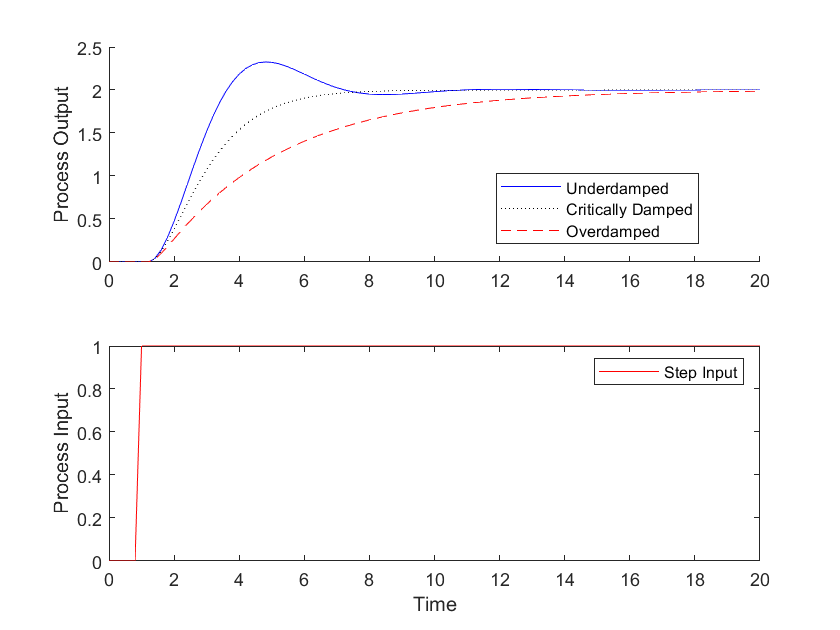

clc; clear all; close all;
% specify number of steps
ns = 100;
% define time points
t = linspace(0,ns/5.0,ns+1);

% default process model
Kp = 2.0;
taus = 1.0;
thetap = 0.0;
zeta = 1.0;
stepinput = 6;

% overdamped step response
zeta = 2.0;
[pv1,op1] = calc_response(t, Kp, taus,zeta,thetap,stepinput);

% critically damped step response
zeta = 1.0;
[pv2,op2] = calc_response(t, Kp, taus,zeta,thetap,stepinput);

% underdamped step response
zeta = 0.5;
[pv3,op3] = calc_response(t, Kp, taus,zeta,thetap,stepinput);

figure(1);

subplot(2,1,1)
    hold on
    p1 = plot(t,pv3(:,1),'b-');
    p2 = plot(t,pv2(:,1),'k:');
    p3 = plot(t,pv1(:,1),'r--');
    legend([p1, p2, p3],{'Underdamped','Critically Damped','Overdamped'}, "Location","best")
    hold off
    ylabel('Process Output')

subplot(2,1,2)
    p4 = plot(t,op1,'r-');
    legend('Step Input')
    ylabel('Process Input')
    hold off
    xlabel('Time')

## Graphically Fit Second Order Response

Oscillating systems need a different type of model than a first order model form for an acceptable approximation. Oscillations imply that the system is an underdamped system. A second order approximation is given by the following equation in the time domain


$$\tau_s^2 \frac{d^2y}{dt^2} + 2 \zeta \tau_s \frac{dy}{dt} + y = K_p \, u\left(t-\theta_p \right)$$


with output $y(t)$, input $u(t)$ and four unknown parameters. The four parameters are the gain $K_p
$, damping factor $\zeta$, second order time constant $\tau_s$, and dead time $\theta_p$.

The following are steps to obtain a graphical approximation of a step response of an underdamped (oscillating) second order system. An underdamped system implies that $0 \le \zeta < 1$.

- Find $\Delta y$ from step response.

- Find $\Delta u$ from step response.

- Calculate $K_p = {\Delta y} / {\Delta u}$.

- Calculate damping factor $\zeta$ from overshoot $OS$ or decay ratio $DR$.

- Calculate $\tau_s$ from equations for rise time $t_r$, peak time $t_p$, or period $P$.

% specify number of steps
ns = 120;
% ns =100;
% define time points
t = linspace(0,ns/10.0,ns+1);
% t = linspace(0,ns/5.0,ns+1);

% default process model
Kp = 2.0;
taus = 0.5;
thetap = 2.0;
zeta = 0.15;
stepinput = 10;
% zeta = 0.5;


% underdamped step response
% (pv,op) = calc_response(t,model)
[pv,op] = calc_response(t, Kp, taus,zeta,thetap,stepinput);

% rename parameters
tau = taus;
zeta = zeta;
du = 2.0;
s = 3.0;

% peak time
tp = pi * tau / sqrt(1.0-zeta^2);
% rise time
tr = tau / (sqrt(1.0-zeta^2)) * (pi-acos(zeta));
% overshoot ratio
os = exp(-pi * zeta / (sqrt(1.0-zeta^2)));
% decay ratio
dr = os^2;
% period
p = 2.0 * pi * tau / (sqrt(1.0-zeta^2));

disp('Summary of response')

Summary of response


disp('rise time: ')

rise time: 


tr

tr = 0.8705

disp('peak time: ')

peak time: 


tp

tp = 1.5888

disp('overshoot: ')

overshoot: 


os

os = 0.6209

disp('decay ratio: ')

decay ratio: 


dr

dr = 0.3855

disp('period: ')

period: 


p

p = 3.1775

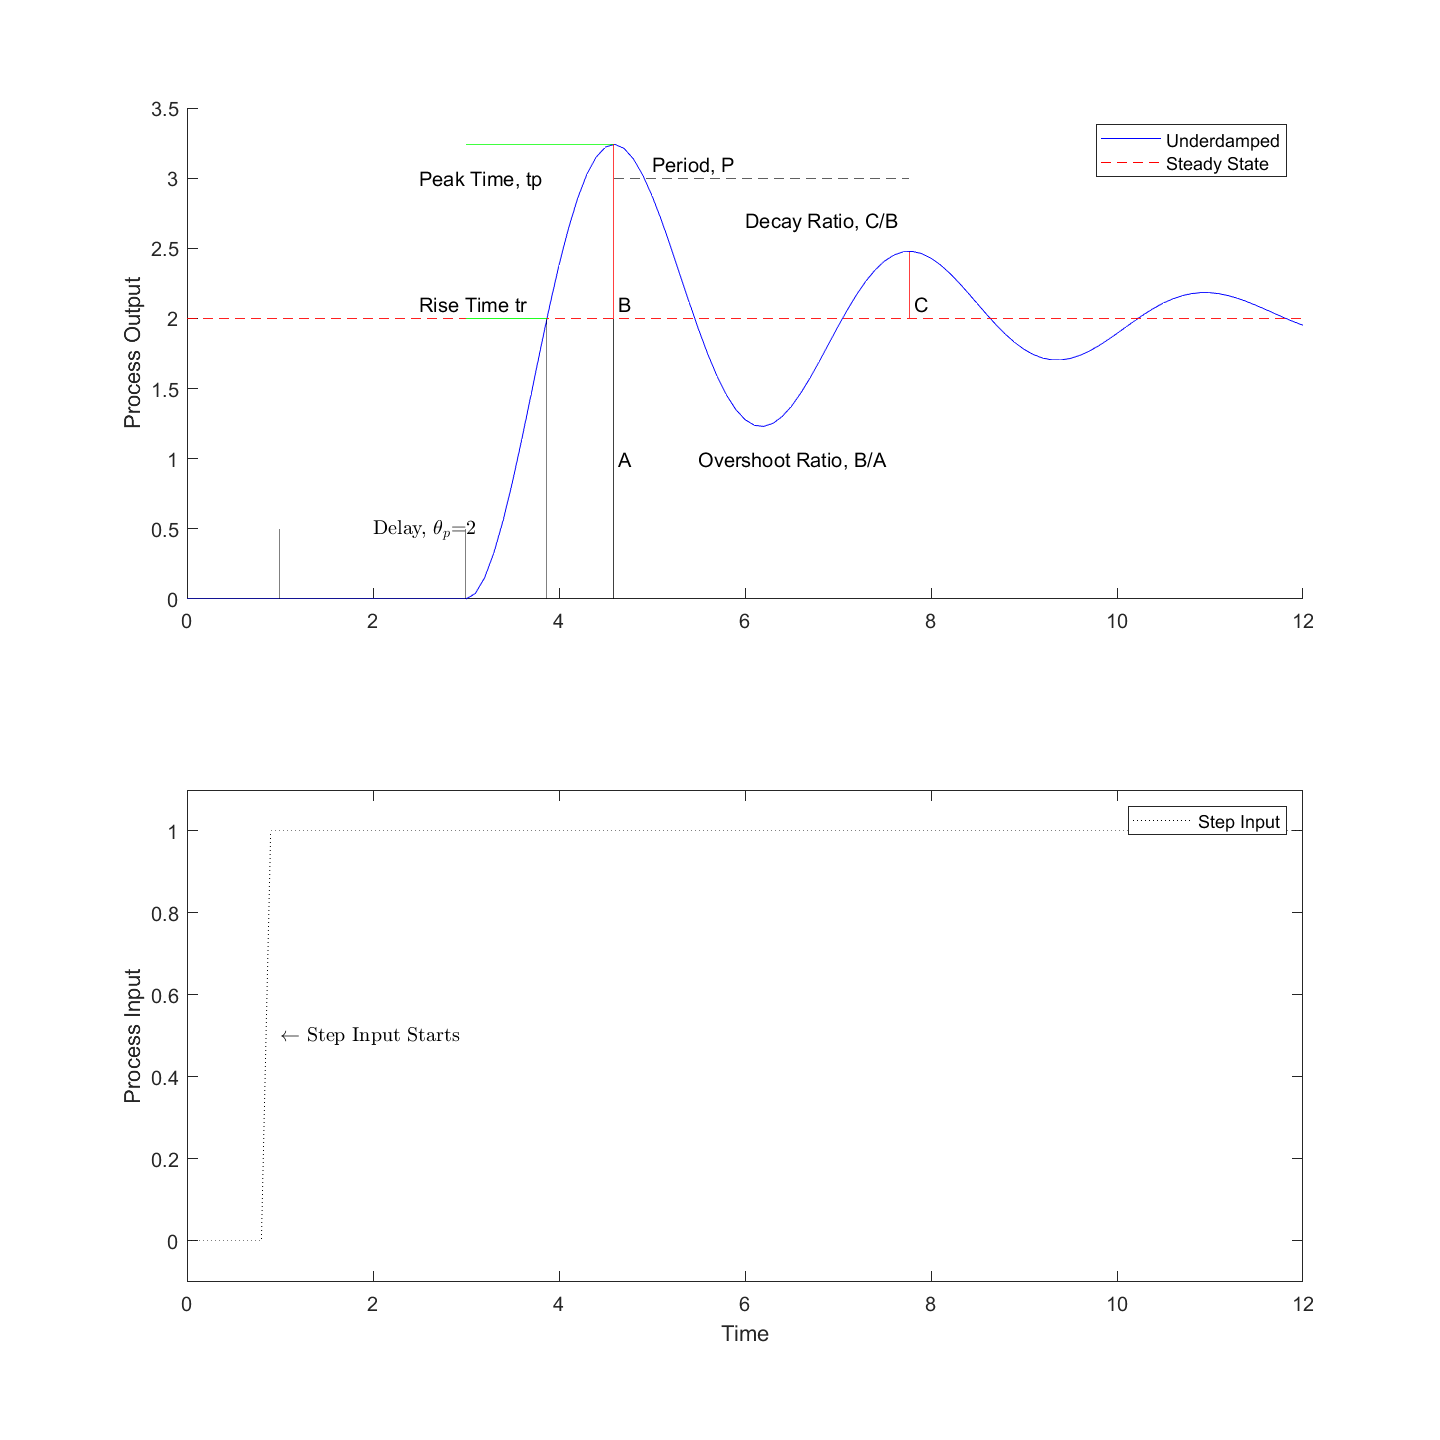


f=figure(3);
f.Position = [10 10 960 960];


subplot(2,1,1)
    hold on
    p6 = plot(t,pv(:,1),'b-');
    p7 = plot([0,max(t)],[2.0,2.0],'r--');
    plot([1,1],[0,0.5],'k-')
    plot([3,3],[0,0.5],'k-')
    plot([3+tr,3+tr],[0,2],'k-')
    plot([3+tp,3+tp],[0,2],'k-')
    plot([3,3+tr],[2,2],'g-')
    plot([3,3+tp],[2*(1+os),2*(1+os)],'g-')
    plot([3+tp,3+tp+p],[3,3],'k--')
    plot([3+tp,3+tp],[2,2*(1.0+os)],'r-')
    plot([3+tp+p,3+tp+p],[2,2*(1+os*dr)],'r-')
    hold off
    legend([p6, p7],{'Underdamped','Steady State'})
    ylabel('Process Output')

%Labels
txt = 'Delay, $\theta_p$=2';
text(2, 0.5,txt, 'Interpreter',"latex")

txt = 'Rise Time tr';
text(2.5,2.1,txt)

txt = 'Peak Time, tp';
text(2.5,3,txt)

txt = 'Period, P';
text(5,3.1,txt)

txt = 'A';
text(3+tp+0.05,1.0,txt)

txt = 'B';
text(3+tp+0.05,2.1,txt)

txt = 'C';
text(3+tp+p+0.05,2.1,txt)

txt = 'Decay Ratio, C/B';
text(6,2.7,txt)

txt = 'Overshoot Ratio, B/A';
text(5.5,1.0,txt)

subplot(2,1,2)
    plot(t,op,'k:')
    ylim([-0.1,1.1])
    legend('Step Input')
    ylabel('Process Input')
    xlabel('Time')

txt = '$\leftarrow$ Step Input Starts';
text(1.0, 0.5, txt,'Interpreter',"latex")

The graphical metrics are dependent on $\zeta$ and $\tau_s$ with the following correlations. For example, it is easiest to use equations for overshoot and decay ratio to calculate $\zeta$. The value for $\tau_s$ can then be calculated from rise time $t_r$, peak time $t_p$, or period $P$.

- Rise time $t_r$: amount of time to first cross the steady state level (after accounting for dead time).


$$t_r = \frac{\tau_s}{\sqrt{1-\zeta^2}}\left( \pi - cos^{-1} \zeta \right)$$


- Peak time $t_p$: amount of time to reach the first peak (after accounting for dead time).


$$t_p = \frac{\pi \tau_s}{\sqrt{1-\zeta^2}} \quad \quad \tau_s = \frac{\sqrt{1-\zeta^2}}{\pi}t_p$$


- Overshoot ratio $OS$: amount that first oscillation surpasses the steady state level relative to the steady state change


$$OS = \exp\left({-\frac{\pi \zeta}{\sqrt{1-\zeta^2}}}\right) \quad \quad \zeta = \sqrt{\frac{\left(\ln(OS)\right)^2}{\pi^2 + \left(\ln(OS)\right)^2}}$$


- Decay ratio $DR$: fractional size of successive peaks


$$DR = OS^2 = \exp\left({-\frac{2 \pi \zeta}{\sqrt{1-\zeta^2}}}\right)$$


- Period $P$: the length of time for an oscillation from peak to peak


$$P = \frac{2 \pi \tau_s}{\sqrt{1-\zeta^2}} \quad \quad \tau_s = \frac{\sqrt{1-\zeta^2}}{2 \pi}P$$


Another method to obtain the parameters is with an optimization method such as minimizing a sum of squared errors differences between measured and predicted values.

## Functions

function dy = process(t, x, u,Kp,taus,zeta)
    % Kp = process gain
    % taus = second order time constant
    % zeta = damping factor
    y = x(1);
    dydt = x(2);
    dy2dt2 = (-2.0*zeta*taus*dydt - y + Kp*u)/taus^2;
    dy = [dydt; dy2dt2];
end

function [pv,op] = calc_response(t,Kp,taus,zeta,thetap,stepinput)

    % specify number of steps
    ns = length(t)-1;
    delta_t = t(2)-t(1);

    % storage for recording values
    op = zeros(ns+1,1);  % controller output
    pv = zeros(ns+1,2);  % process variable
    
    % step input
    op(stepinput:end) = 1.0;

    % Simulate time delay
    ndelay = int64(ceil(thetap / delta_t));

    % loop through time steps    
    for i = 1:ns
        % implement time delay
        iop = max([1,i-ndelay-1]);
        ts = [delta_t*(i-1),delta_t*i];
        [t, y] = ode45(@(t, y) process(t,y,op(iop),Kp,taus, zeta),ts, pv(i,:)');
        y;
        pv(i+1,:) = y(end,:);
    end
end
